% Cargar los datos desde un archivo
data = constanteestaticaS3; % Asegúrate de ajustar la ruta al archivo de datos
tiempo = data.VarName2;
angulo = data.Angle1;

% Encontrar los picos máximos positivos
[peaks, locs] = findpeaks(angulo, 'MinPeakHeight', 0);
tiempos_peaks = tiempo(locs);

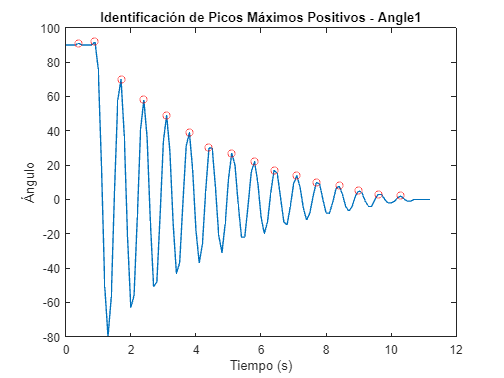

Ajuste exponencial para Angle1


     General model Exp1:
     f(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =       111.1  (104.1, 118.1)
       b =     -0.2858  (-0.3118, -0.2598)


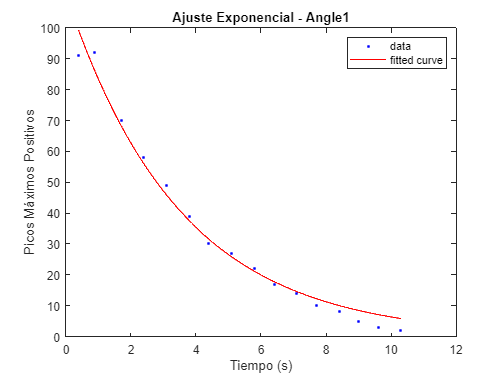

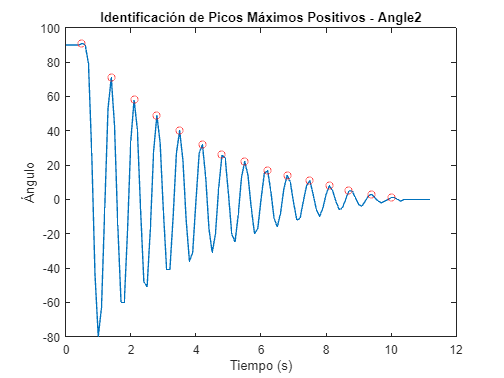

Ajuste exponencial para Angle2


     General model Exp1:
     f(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =       107.9  (102.9, 112.9)
       b =     -0.2986  (-0.3168, -0.2804)


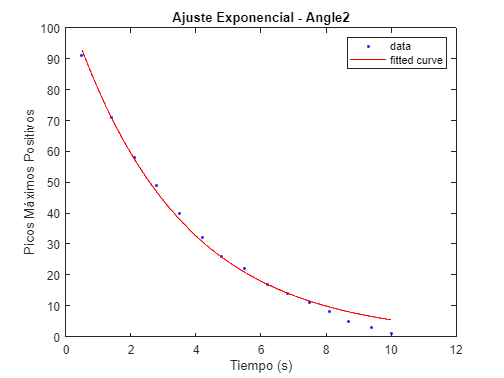

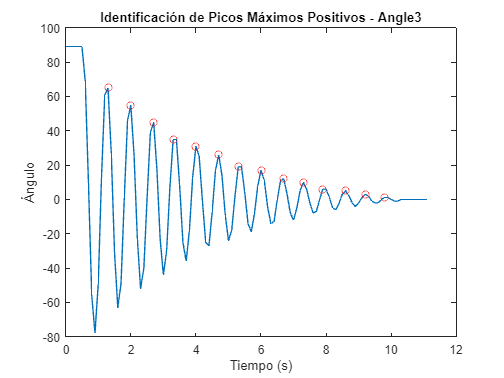

Ajuste exponencial para Angle3


     General model Exp1:
     f(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =       101.2  (92.99, 109.3)
       b =     -0.3132  (-0.3402, -0.2862)


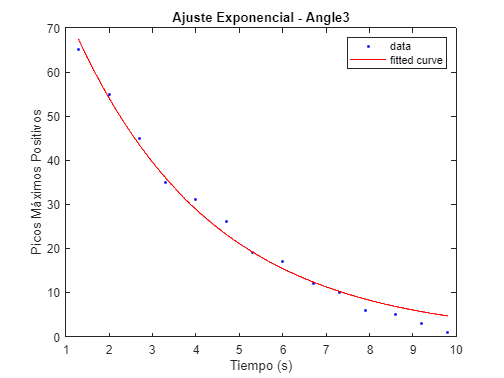

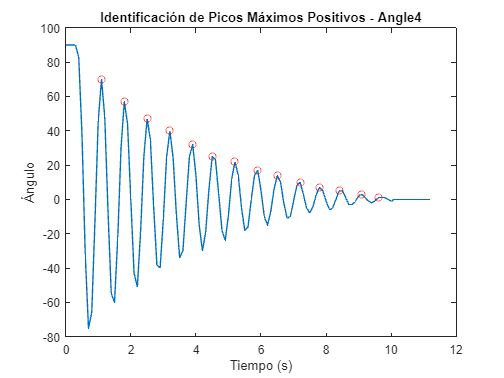

Ajuste exponencial para Angle4


     General model Exp1:
     f(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =       100.7  (93.53, 107.9)
       b =     -0.3097  (-0.3347, -0.2847)


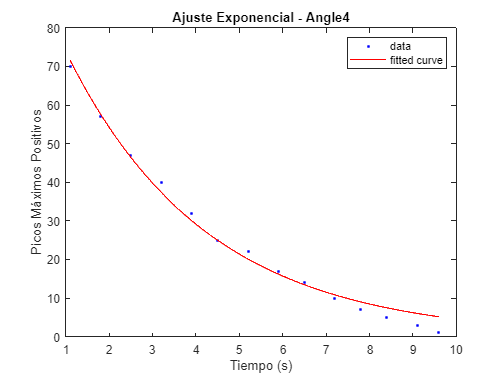

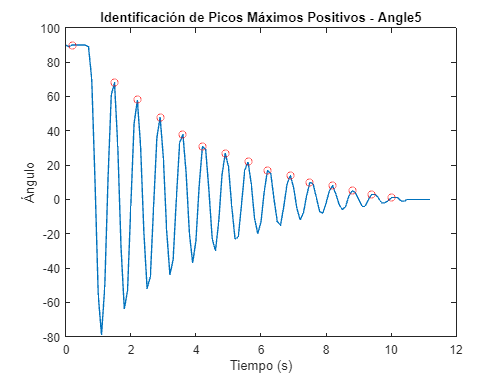

Ajuste exponencial para Angle5


     General model Exp1:
     f(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =       99.92  (93.59, 106.3)
       b =      -0.278  (-0.302, -0.254)


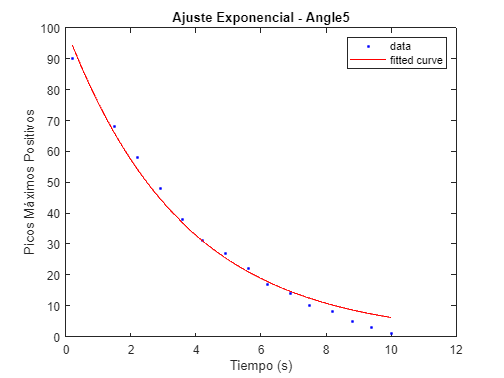

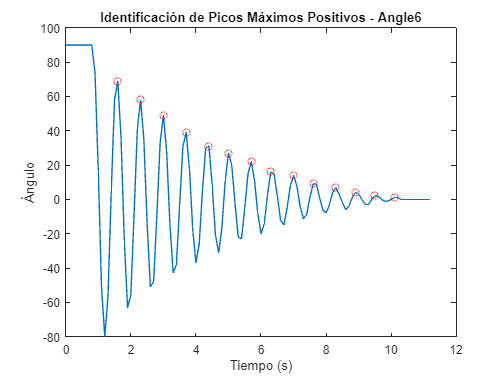

Ajuste exponencial para Angle6


     General model Exp1:
     f(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =         119  (107.2, 130.8)
       b =     -0.3137  (-0.3441, -0.2833)


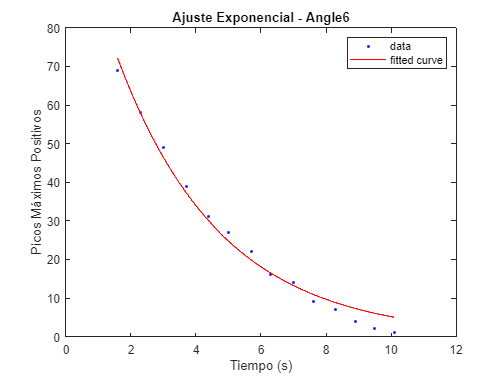

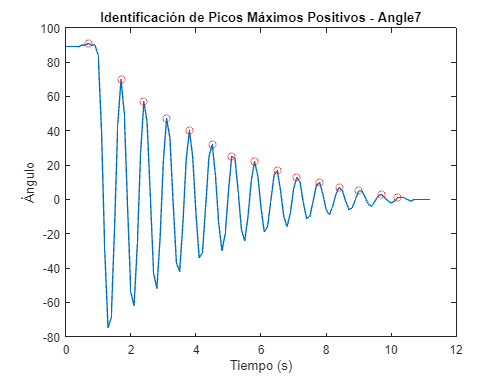

Ajuste exponencial para Angle7


     General model Exp1:
     f(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =         115  (108.8, 121.3)
       b =     -0.2977  (-0.3174, -0.2779)


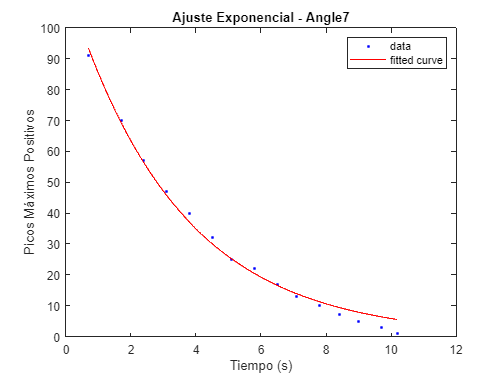

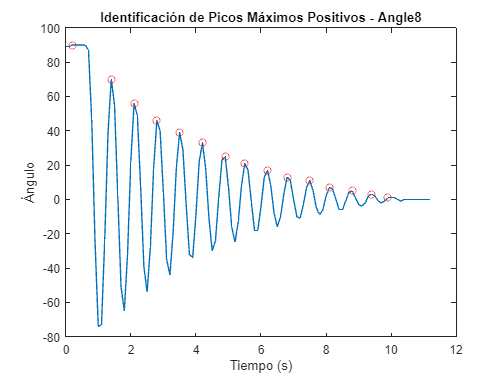

Ajuste exponencial para Angle8


     General model Exp1:
     f(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =       99.45  (93.79, 105.1)
       b =     -0.2842  (-0.3066, -0.2619)


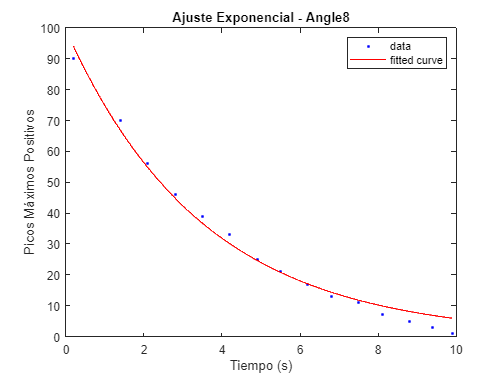

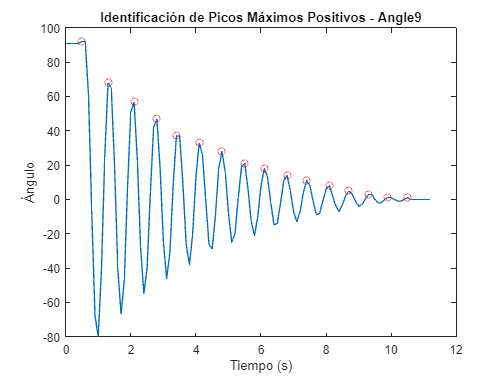

Ajuste exponencial para Angle9


     General model Exp1:
     f(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =       106.2  (100.6, 111.9)
       b =     -0.3033  (-0.3245, -0.2821)


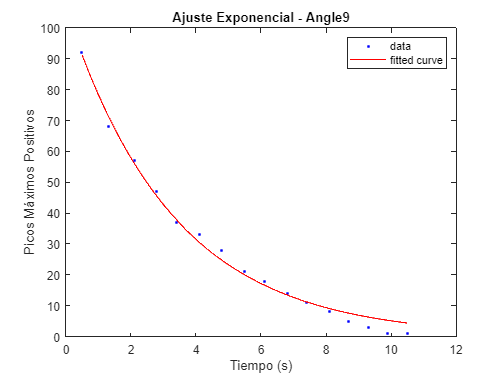


data = constanteestaticaS3; 
tiempo = data.VarName2; % Suponiendo que la columna de tiempo se llama 'Tiempo_s_'

% Nombres de las columnas de ángulos
columnas_angulos = {'Angle1', 'Angle2', 'Angle3', 'Angle4', 'Angle5', 'Angle6', 'Angle7', 'Angle8', 'Angle9'};

for i = 1:length(columnas_angulos)
    % Obtener los datos de la columna actual
    angulo = data.(columnas_angulos{i});
    
    % Encontrar los picos máximos positivos
    [peaks, locs] = findpeaks(angulo, 'MinPeakHeight', 0);
    
    % Obtener los tiempos correspondientes a los picos
    tiempos_peaks = tiempo(locs);
    
    % Graficar los picos
    figure;
    plot(tiempo, angulo);
    hold on;
    plot(tiempos_peaks, peaks, 'ro');
    xlabel('Tiempo (s)');
    ylabel('Ángulo');
    title(['Identificación de Picos Máximos Positivos - ', columnas_angulos{i}]);
    hold off;
    
    % Ajustar una curva exponencial a los picos
    f = fit(tiempos_peaks, peaks, 'exp1');
    disp(['Ajuste exponencial para ', columnas_angulos{i}]);
    disp(f);
    
    % Graficar la curva ajustada
    figure;
    plot(f, tiempos_peaks, peaks);
    xlabel('Tiempo (s)');
    ylabel('Picos Máximos Positivos');
    title(['Ajuste Exponencial - ', columnas_angulos{i}]);
end